# Ising Hessian at finite temperature

This code implement analytical calculations of correlation functions *with details*.

X = PauliI(1, 1, 1);
Y = PauliI(1, 1, 2);
Z = PauliI(1, 1, 3);
I = eye(2);

% setting up initial parameters, taken care of by the construct_H function
% N = 10; g = 0.5;
% [H, Hloc] = hIM(1, g, 0, N, 'PBC'); % Hamiltonian at fixed coupling g
% h = Hloc(:, :, 1);
% 
% Z = @(b) trace(expm(-b*H)); % partition function at fixed g

% set up temperature, in the unit of J/k_B
TT = linspace(0, 5, 40);
% TT = [linspace(0.04, 0.5, 20)];
bb = 1./TT; % the inverse temperatures

set(groot, 'defaultTextInterpreter', 'none');
set(groot, 'defaultAxesFontSize', 15);
set(groot, 'defaultTextFontSize', 15);


## Thermal average of energy

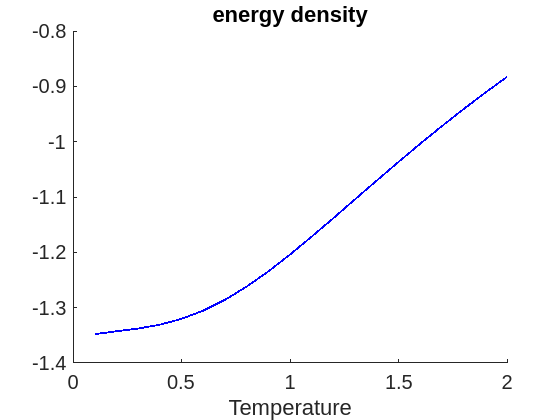

% eta = 1; % parity factor from Mbeng2020, =1 for the clean case
eps = @(N, p, g) sqrt(1 + g^2 - 2*g*cos(kk(N, p))); % energy spectrum: vector of eps(k)

% energy via single-particle excitations
N = 8; g = 1.1;
eta = empiricEta(g);
analyticE = zeros(1, size(TT, 2));
analyticX = zeros(1, size(TT, 2));
analyticZZ = zeros(1, size(TT, 2));
for i = 1:size(TT, 2)
    for mu = 1:N
        for p = [0, 1]
            EE = eps(N, p, g);
            [ccd, cdc] = sp_excit(bb(i), mu, p, N, g, eta);
            analyticE(i) = analyticE(i) + (cdc-ccd) * EE(mu);
            [ZZ, X] = analyticC_v2(N, g, bb(i));
            analyticX(i) = X;
            analyticZZ(i) = ZZ;
        end
    end
end

analyticE = analyticE/N;

%
% energy via exact diagonalization
[edH, edh, edZ] = construct_H(N, g);
edE = zeros(1, size(TT, 2));
edX = zeros(1, size(TT, 2));
edZZ = zeros(1, size(TT, 2));
for i = 1:size(TT, 2)
    edE(i) = trace(edH * expm(-bb(i)*edH)) / edZ(bb(i)) / N;
    edX(i) = trace(PauliI(N, 1, 1) * expm(-bb(i)*edH)) / edZ(bb(i));
    edZZ(i) = trace(PauliI(N, 1, 3) * PauliI(N, 2, 3) * expm(-bb(i)*edH)) / edZ(bb(i));
end
%
figure()
hold on
% plot(TT, edE, 'ro')
plot(TT, analyticE, 'b-', 'LineWidth', 1.4)
hold off
xlabel('Temperature')
title('energy density')

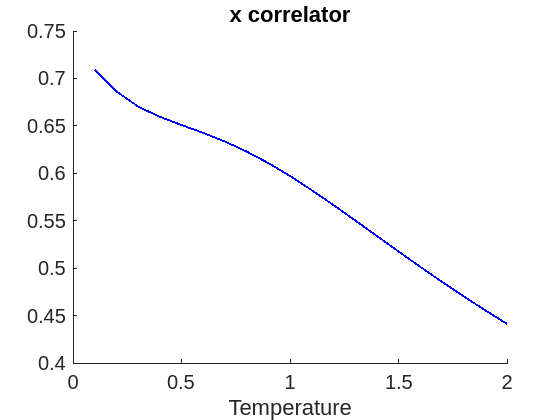

figure()
hold on
% plot(TT, edX, 'ro')
plot(TT, analyticX, 'b-', 'LineWidth', 1.4)

hold off
title('x correlator')
xlabel('Temperature')

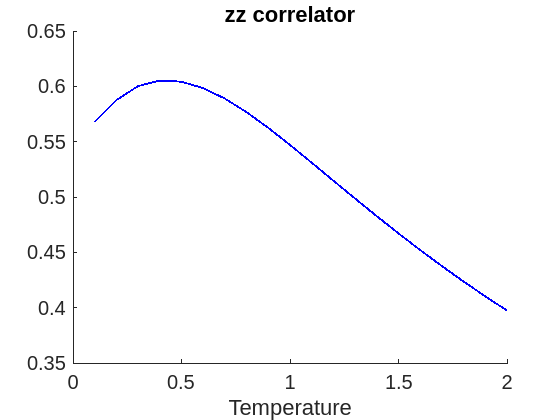

figure()
hold on
% plot(TT, edZZ, 'ro')
plot(TT, analyticZZ, 'b-', 'LineWidth', 1.4)
title('zz correlator')
xlabel('Temperature')
hold off

Plotting the (analytically calculated) correlators on the same graph

N = 10;



g = 0.5;
eta = empiricEta(g);
analyticE = zeros(1, size(TT, 2));
analyticX = zeros(1, size(TT, 2));
analyticZZ = zeros(1, size(TT, 2));
for i = 1:size(TT, 2)
    for mu = 1:N
        for p = [0, 1]
            EE = eps(N, p, g);
            [ccd, cdc] = sp_excit(bb(i), mu, p, N, g, eta);
            analyticE(i) = analyticE(i) + (cdc-ccd) * EE(mu);
            [ZZ, X] = analyticC_v2(N, g, bb(i));
            analyticX(i) = X;
            analyticZZ(i) = ZZ;
        end
    end
end

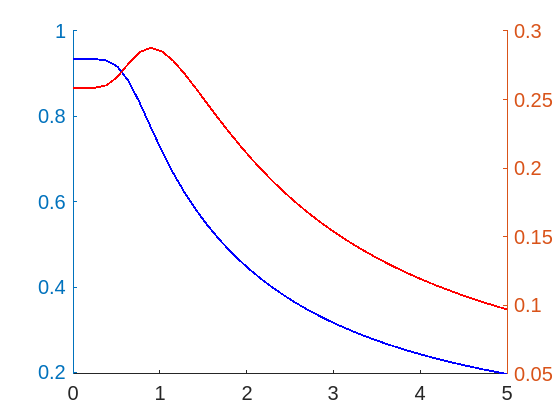


figure()
hold on
yyaxis left
plot(TT, [analyticZZ(2), analyticZZ(2:end)], 'b-', 'LineWidth', 1.4, 'Tag', 'e')
yyaxis right
plot(TT, [analyticX(2), analyticX(2:end)], 'r-', 'LineWidth', 1.4)

xlim([0,5])

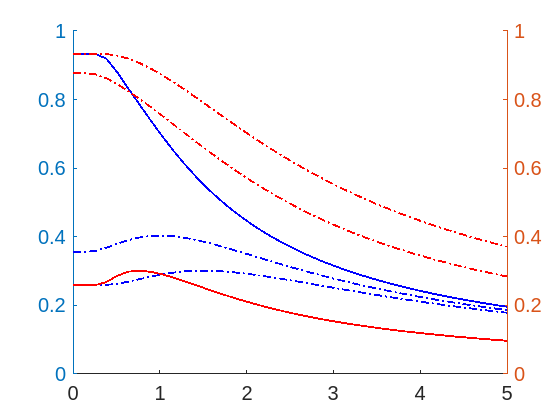

g = 2;
eta = empiricEta(g);
analyticE = zeros(1, size(TT, 2));
analyticX = zeros(1, size(TT, 2));
analyticZZ = zeros(1, size(TT, 2));
for i = 1:size(TT, 2)
    for mu = 1:N
        for p = [0, 1]
            EE = eps(N, p, g);
            [ccd, cdc] = sp_excit(bb(i), mu, p, N, g, eta);
            analyticE(i) = analyticE(i) + (cdc-ccd) * EE(mu);
            [ZZ, X] = analyticC_v2(N, g, bb(i));
            analyticX(i) = X;
            analyticZZ(i) = ZZ;
        end
    end
end

yyaxis left
plot(TT, [analyticZZ(2), analyticZZ(2:end)], 'b-.', 'LineWidth', 1.4, 'Tag', 'e')
yyaxis right
plot(TT, [analyticX(2), analyticX(2:end)], 'r-.', 'LineWidth', 1.4)

# Final plot

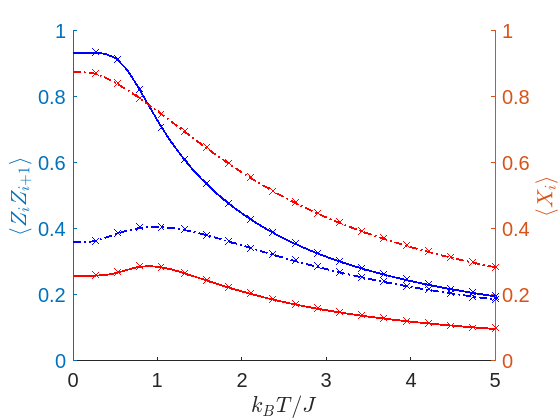

% Exact diagonalization at N = 10
figure()
hold on

N = 10; g = 0.5; TT = linspace(0, 5, 20); bb = 1./TT;
[edH, edh, edZ] = construct_H(N, g);
edE = zeros(1, size(TT, 2));
edX = zeros(1, size(TT, 2));
edZZ = zeros(1, size(TT, 2));
for i = 1:size(TT, 2)
    edE(i) = trace(edH * expm(-bb(i)*edH)) / edZ(bb(i)) / N;
    edX(i) = trace(PauliI(N, 1, 1) * expm(-bb(i)*edH)) / edZ(bb(i));
    edZZ(i) = trace(PauliI(N, 1, 3) * PauliI(N, 2, 3) * expm(-bb(i)*edH)) / edZ(bb(i));
end


yyaxis left
plot(TT, edZZ, 'bx')
yyaxis right
plot(TT, edX, 'rx')

% Calculation at N = 30
N = 10; g = 0.5; TT = linspace(0, 5, 40); bb = 1./TT;
eta = empiricEta(g);
analyticE = zeros(1, size(TT, 2));
analyticX = zeros(1, size(TT, 2));
analyticZZ = zeros(1, size(TT, 2));
for i = 1:size(TT, 2)
    for mu = 1:N
        for p = [0, 1]
            EE = eps(N, p, g);
            [ccd, cdc] = sp_excit(bb(i), mu, p, N, g, eta);
            analyticE(i) = analyticE(i) + (cdc-ccd) * EE(mu);
            [ZZ, X] = analyticC_v2(N, g, bb(i));
            analyticX(i) = X;
            analyticZZ(i) = ZZ;
        end
    end
end


hold on
yyaxis left
plot(TT, [analyticZZ(2), analyticZZ(2:end)], 'b-', 'LineWidth', 1.4)
yyaxis right
plot(TT, [analyticX(2), analyticX(2:end)], 'r-', 'LineWidth', 1.4)

% change g
N = 10; g = 1.5; TT = linspace(0, 5, 20); bb = 1./TT;
[edH, edh, edZ] = construct_H(N, g);
edE = zeros(1, size(TT, 2));
edX = zeros(1, size(TT, 2));
edZZ = zeros(1, size(TT, 2));
for i = 1:size(TT, 2)
    edE(i) = trace(edH * expm(-bb(i)*edH)) / edZ(bb(i)) / N;
    edX(i) = trace(PauliI(N, 1, 1) * expm(-bb(i)*edH)) / edZ(bb(i));
    edZZ(i) = trace(PauliI(N, 1, 3) * PauliI(N, 2, 3) * expm(-bb(i)*edH)) / edZ(bb(i));
end

yyaxis left
plot(TT, edZZ, 'bx')
yyaxis right
plot(TT, edX, 'rx')

% Calculation at N = 30
N = 10; g = 1.5; TT = linspace(0, 5, 40); bb = 1./TT;
eta = empiricEta(g);
analyticE = zeros(1, size(TT, 2));
analyticX = zeros(1, size(TT, 2));
analyticZZ = zeros(1, size(TT, 2));
for i = 1:size(TT, 2)
    for mu = 1:N
        for p = [0, 1]
            EE = eps(N, p, g);
            [ccd, cdc] = sp_excit(bb(i), mu, p, N, g, eta);
            analyticE(i) = analyticE(i) + (cdc-ccd) * EE(mu);
            [ZZ, X] = analyticC_v2(N, g, bb(i));
            analyticX(i) = X;
            analyticZZ(i) = ZZ;
        end
    end
end

yyaxis left
plot(TT, [analyticZZ(2), analyticZZ(2:end)], 'b-.', 'LineWidth', 1.4)
yyaxis right
plot(TT, [analyticX(2), analyticX(2:end)], 'r-.', 'LineWidth', 1.4)

yyaxis left
ylabel('$\langle Z_i Z_{i+1} \rangle$', Interpreter='latex')
yyaxis right
ylabel('$\langle X_i \rangle$', Interpreter='latex')

xlabel('$k_BT/J$', Interpreter='latex')

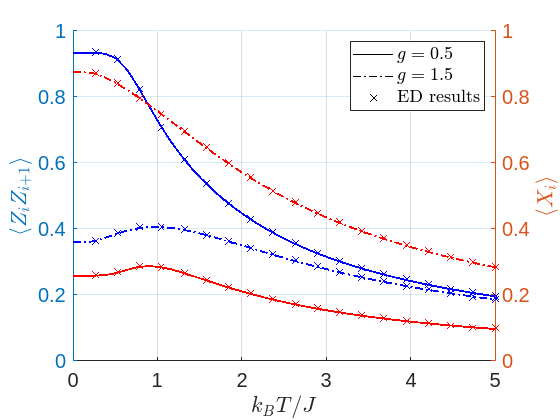

grid on
L1 = plot(nan, nan, 'k-');
L2 = plot(nan, nan, 'k-.');
L3 = plot(nan, nan, 'kx');
legend([L1, L2, L3], {'$g=0.5$', '$g=1.5$', 'ED results'})
legend(Interpreter="latex")

% Verifying the correlation functions are the same
N = 7; 
[ETA, M, F, G] = analyticP(N, g);
[Mij, Fij, Gij] = analyticM(N, g, 1, 1);

% ETA(0)
% ETA(1)
format long
b = 0.2; g = 0.8;
eta = empiricEta(g);
[aZZ, aX] = analyticC(N, g, b);
[aZZ1, aX1] = analyticC_v1(N, g, b);
[aZZ2, aX2] = analyticC_v2(N, g, b);
[eZZ, eX] = gen_therm_av(N, g, b);
% 
% [ccd0, cdc0] = sp_excit(2, mu, 0, N, g, eta);
% [ccd1, cdc1] = sp_excit(2, mu, 1, N, g, eta);
% ccd0 + ccd1 + cdc0 + cdc1;
disp([aZZ; aZZ1; aZZ2; eZZ]);

   0.505287611187454
   0.167126484811827
   0.194221344130166
   0.194221344130167



disp([aX; aX1; aX2; eX]);

   0.296760632951828
   0.056791554964028
   0.154603412566101
   0.154603412566101




[H, h, Z] = construct_H(N, g);
en = trace(H * expm(-b*H))/Z(b)/N;
disp([-aZZ-g*aX; ...
    -aZZ1-g*aX1; ...
    -aZZ2-g*aX2; ...
    en]);

  -0.742696117548916
  -0.212559728783049
  -0.317904074183047
  -0.317904074183048



Large $N$ using analytical derivation instead of ED. Computation of the Hessian eigenvalues.

% N = 10 case
% find the transition temperature
N = 10; g = 1; b = 0.1;

analyticEig(N, g, b)

ans =    NaN



% Plot: the lowest eigenvalue with respect to temperature at some fixed
% couplings
gg = [0,0.1,2.3];
TT = [linspace(0.02, 1, 15)];

gT = zeros(size(gg, 2), size(TT, 2));
gT1 = zeros(size(gg, 2), size(TT, 2));
gT8Ana = zeros(size(gg, 2), size(TT, 2));
gT8Num = zeros(size(gg, 2), size(TT, 2));
for i = 1:size(gg, 2)
    g = gg(i);
    for j = 1:size(TT, 2)
        b = TT(j)^(-1);
        N = 20;
        gT(i, j) = analyticEig(N, g, b);
        N = 4;
        gT1(i, j) = analyticEig(N, g, b);
        N = 8;
        gT8Ana(i, j) = analyticEig(N, g, b);
        gT8Num(i, j) = -max(real(numEig(N, g, b)))/2;
    end
end


## ED at zero temperature, Hessian eigenvalues across the phase diagram

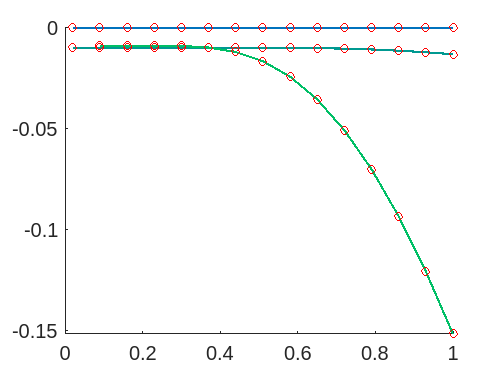

figure()
hold on
for i = 1:size(gg, 2)
    plot(TT, gT8Ana(i, :), 'LineWidth', 1.6, 'LineStyle', '-', 'Color', cs(i, :));
    plot(TT, gT8Num(i, :), 'ro');
end
hold off

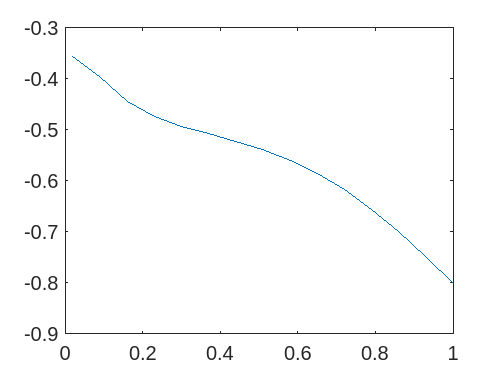

format short
lams = zeros(3, length(TT));
for i = 1:length(TT)
    [lam, M] = numEig(8, 1, TT(i)^(-1));
    lams(:, i) = lam;
end
figure()
plot(TT, min(lams))

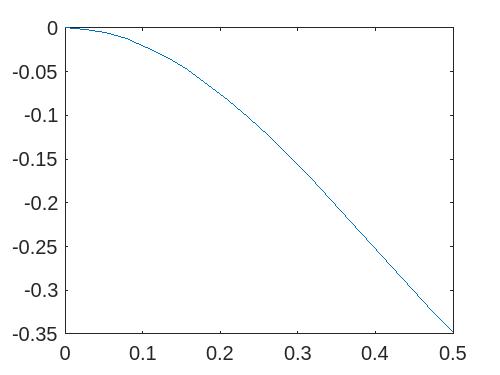

gg = linspace(0, 0.5, 20);
glam = zeros(3, length(gg));
for i = 1:length(gg)
    [H, Hloc] = hIM(1, gg(i), 0, N, 'PBC');
    h = Hloc(:, :, 1);
    [spec, l] = eig(H);
    GS = spec(:, 1);
    M = zeros(3);
    for a = 1:3
        for b = 1:3
            A = PauliI(N, 1, a);
            B = PauliI(N, 1, b);
            O = A*B*h + h*A*B - 2*A*h*B;
            M(a, b) = -GS'*O*GS;
        end
    end
    ll = eig(M, "vector");
    glam(:, i) = sort(real(ll));
end
figure()
plot(gg, min(glam))

figure()
c1 = [0, 0.4470, 0.7410];
c2 = [0, 0.6, 0.57];
c3 = [0, 0.75, 0.4];
cs = [c1; c2; c3]

cs =                    0   0.447000000000000   0.741000000000000
                   0   0.600000000000000   0.570000000000000
                   0   0.750000000000000   0.400000000000000


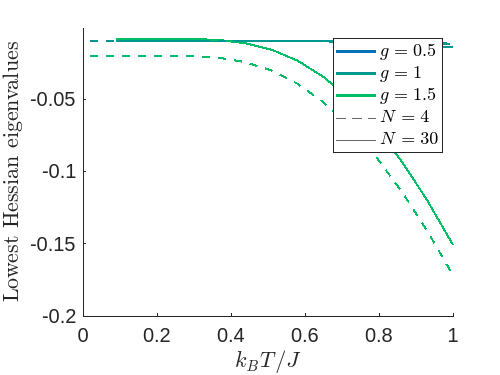

hold on
for i = 1:size(gg, 2)
    plot(TT, gT(i, :), 'LineWidth', 1.6, 'LineStyle', '-', 'Color', cs(i, :));
end
yline(0, '--', 'Visible', 'on')
yline(0, 'Visible', 'on')
for i = 1:size(gg, 2)
    plot(TT, gT1(i, :), 'LineWidth', 1.6, 'LineStyle', '--', 'Color', cs(i, :));
end
yline(0, 'r-')
hold off
legend({'$g=0.5$', '$g=1$', '$g=1.5$', '$N=4$', '$N=30$'},Interpreter="latex")
xlabel('$k_BT/J$', Interpreter='latex')
ylabel('Lowest Hessian eigenvalues')

N = 9; g = 0.4; b = 20;
numEig(N, g, b)

ans =  -3.834848698464321 + 0.000000000000000i
 -4.741545785064900 - 0.000000000000000i
  0.253057756770376 + 0.000000000000000i


function [H, h, Z] = construct_H(N, g)
% The definition of Hamiltonian and thermal partition function 
[H, Hloc] = hIM(1, g, 0, N, 'PBC');
h = Hloc(:, :, 1);
Z = @(b) trace(expm(-b*H)); 
end

function Z = analyticZ(N, g, eta)
% Analytical formulation of Z
eps = @(p) sqrt(1 + g^2 - 2*g*cos(kk(N, p)));
% eta = @(p) (-1)^p;
% [eta, ~, ~, ~] = analyticP(N, g);

Z = @(b) 1/2 * (prod(1+exp(-2*b*eps(0))) + eta(0)*prod(1-exp(-2*b*eps(0)))) * exp(b*sum(eps(0))) ...
    + 1/2 * (prod(1+exp(-2*b*eps(1))) + eta(1)*prod(1-exp(-2*b*eps(1)))) * exp(b*sum(eps(1))) ;
end

% the following functions should all be from the expectation perspective
function [ccd, cdc] = sp_excit(b, mu, p, N, g, eta)
% gives thermal expectation for bogoliubon single-particle excitations
% eta = @(p) 1;
% [eta, ~, ~, ~] = analyticP(N, g);
Z = analyticZ(N, g, eta);
E = sqrt(1 + g^2 - 2*g*cos(kk(N, p)));
e = E(mu); % the mu^th excitation mode
cdc = exp(b*sum(E)) * exp(-2*b*e)/2 * (prod_except(1+exp(-2*b*E), mu) - eta(p)*prod_except(1-exp(-2*b*E), mu));
ccd = exp(b*sum(E)) * 1/2 * (prod_except(1+exp(-2*b*E), mu) + eta(p)*prod_except(1-exp(-2*b*E), mu));
cdc = cdc/Z(b);
ccd = ccd/Z(b);
end


function K = kk(N, p)
if mod(N, 2) == 0 % even number of spins
    switch p
        case 0
            K = -(N-1)/N*pi:(2*pi)/N:(N-1)/N*pi;
        case 1
            K = -pi+2*pi/N:(2*pi)/N:pi;
    end
elseif mod(N, 2) == 1 % odd number of spins
    switch p
        case 0
            K = -(N-2)/N*pi:2*pi/N:pi;
        case 1
            K = -(N-1)/N*pi:2*pi/N:(N-1)/N*pi;
    end
end
% if posflag == 1
%     K = K(K>=0);
% end
end

function val = prod_except(A, i)
A(i) = [];
val = prod(A);
end


For the following functions, see Sec 9 in Mbeng

function [Mij, Fij, Gij] = analyticM(N, g, i, j)
% compute the parity factors via correlation functions
d = j-i;
eps = @(p) sqrt(1 + g^2 - 2*g*cos(kk(N, p)));
cosk = @(p) (g-cos(kk(N, p)))./eps(p);
sink = @(p) sin(kk(N, p))./eps(p);
u2 = @(p) (1+cosk(p))/2;
uv = @(p) sink(p)/2;

Gij = 0; Fij = 0;
for p = [0, 1]
    Gij = Gij + sum(u2(p).*exp(-1i*kk(N, p)*d));
    Fij = Fij + (-1i) * sum(uv(p).*exp(-1i*kk(N, p)*d));
end


Gij = trim_imag(Gij)/N;
Fij = trim_imag(Fij)/N;
Mij = isequal(i, j) - (Gij + Fij);
end

function [eta, M, F, G] = analyticP(N, g)
% arrange the matrix
M = zeros(N);
F = zeros(N);
G = zeros(N);
for i = 1:N
    for j = 1:N
        [Mij, Fij, Gij] = analyticM(N, g, i, j);
        M(i, j) = Mij;
        F(i, j) = Fij;
        G(i, j) = Gij;
    end
end
eta = @(p) (-1)^p * (-1)^N * det(M);
end

function y = trim_imag(x)
y = x;
if abs(imag(x)) < 1e-8
    y = real(x);
end
end

function [ZZ, X] = analyticC(N, g, b)
vecZZ = zeros(2, N); % two rows for two parity sectors
vecX = zeros(2, N);
% eta = @(p) (-1)^p;
eta = empiricEta(g);
for p = [0, 1]
    K = kk(N, p);
    E = sqrt(1 + g^2 - 2*g*cos(K));
    for mu = 1:N
        [~, sp] = sp_excit(b, mu, p, N, g, eta);
        vecZZ(p+1, mu) = -2*sin(K(mu))^2/E(mu) * (sp - 1/2)  + 2*cos(K(mu))* (sp*(g-cos(K(mu)))/E(mu)  + 1/2 - 1/2*(g-cos(K(mu)))/E(mu));
        vecX(p+1, mu) = (g - cos(K(mu)))/E(mu) * sp + 1/2 - 1/2*((g - cos(K(mu)))/E(mu));
    end
end
ZZ = 1/2 * (sum(vecZZ, 'all') * (1/N));
X = 1/2 * (sum(vecX, 'all') * (-2/N))+1;

end


function [ZZ, X] = gen_therm_av(N, g, b)
% ED
H = hIM(1, g, 0, N, 'PBC');
expec = @(b, O) trace(O * expm(-b*H))/trace(expm(-b*H));
ZZ = expec(b, PauliI(N, 1, 3)*PauliI(N, 2, 3));
X = expec(b, PauliI(N, 1, 1));
end

function [ZZ, X] = analyticC_v1(N, g, b)
eta = empiricEta(g);
eps = @(p) sqrt(1 + g^2 - 2*g*cos(kk(N, p)));
cosk = @(p) (g-cos(kk(N, p)))./eps(p);
sink = @(p) sin(kk(N, p))./eps(p);
u2 = @(p) (1+cosk(p))/2;
uv = @(p) sink(p)/2;
v2 = @(p) (1-cosk(p))/2;
CCD = zeros(2, N); CDC = zeros(2, N);
for p = [0, 1]
    for mu = 1:N
        [ccd, cdc] = sp_excit(b, mu, p, N, g, eta);
        CCD(p+1, mu) = ccd;
        CDC(p+1, mu) = cdc;
    end
end

G12b = 0; G11b = 0; F12b = 0;
for p = [0, 1]
    G12b = G12b + sum((u2(p).*CCD(p+1, :)+v2(p).*map_vec(CCD(p+1, :), N, p)).*exp(-1i*kk(N, p)));
    G11b = G11b + sum(u2(p).*CCD(p+1, :)+v2(p).*map_vec(CCD(p+1, :), N, p));
    F12b = F12b + sum((uv(p).*CCD(p+1, :)-uv(p).*map_vec(CDC(p+1, :), N, p)).*exp(-1i*kk(N, p)))*(-1i);
end

ZZ = -G12b - F12b;
ZZ = (ZZ+conj(ZZ))/N;
X = 1/2*(G11b/N - 1/2);
end

function [ZZ, X] = analyticC_v2(N, g, b)
eta = empiricEta(g);
eps = @(p) sqrt(1 + g^2 - 2*g*cos(kk(N, p)));
cosk = @(p) (g-cos(kk(N, p)))./eps(p);
sink = @(p) sin(kk(N, p))./eps(p);
u2 = @(p) (1+cosk(p))/2;
uv = @(p) sink(p)/2;
v2 = @(p) (1-cosk(p))/2;
CCD = zeros(2, N); CDC = zeros(2, N);
for p = [0, 1]
    for mu = 1:N
        [ccd, cdc] = sp_excit(b, mu, p, N, g, eta);
        CCD(p+1, mu) = ccd;
        CDC(p+1, mu) = cdc;
    end
end
G12b = 0; G11b = 0; F12b = 0;
for p = [0, 1]
    G12b = G12b + sum(1/N * (exp(-1i*kk(N, p)).*u2(p).*CCD(p+1, :) + ...
        exp(1i*kk(N, p)).*v2(p).*CDC(p+1, :)));
    G11b = G11b + sum(1/N * (u2(p).*CCD(p+1, :) + ...
        v2(p).*CDC(p+1, :)));
    F12b = F12b + 1/N * sum((-1i)*exp(-1i*kk(N, p)).*uv(p).*CCD(p+1, :) + ...
        (-1i)*exp(1i*kk(N, p)).*uv(p).*CDC(p+1, :));
end
% disp([F12b, G12b, G11b]);
ZZ = -F12b-G12b;
ZZ = 2*real(ZZ);
X = 2*G11b - 1;
end



function w = map_vec(v, N, p)
if mod(N, 2) == 0 % even number of spins
    if mod(p, 2) == 0 % even parity sector
        w = fliplr(v);
    elseif mod(p, 2) == 1 % odd parity sector
        vminus = v(1:N/2-1);
        v0 = v(N/2);
        vplus = v(N/2+1:N-1);
        vpi = v(N);
        w = [fliplr(vplus), vpi, fliplr(vminus), v0];
    end
elseif mod(N, 2) == 1 % odd number of spins
    if mod(p, 2) == 0 % even parity sector
        vpm = v(1:N-1);
        vpi = v(N);
        w = [fliplr(vpm), vpi];
    elseif mod(p, 2) == 1 % odd parity sector
        vminus = v(1:(N-1)/2);
        v0 = v((N-1)/2+1);
        vplus = v((N+1)/2+1:N);
        w = [fliplr(vplus), v0, fliplr(vminus)];
    end
end
end

function eta = empiricEta(g)
if g < 1
    eta = @(p) 1;
else
    eta = @(p) (-1)^p;
end
end

function lam = analyticEig(N, g, b)
[z, x] = analyticC_v2(N, g, b);
M = [2*z+2*g*x, 2*1i*g;
    -2*1i*g, 2*g*x];
[~, eigval] = eig(M, 'vector');
lam = min(eigval);
end

function [lam, M] = numEig(N, g, b)
[H, Hloc] = hIM(1, g, 0, N, 'PBC');
h = Hloc(:, :, 1);
expec = @(b, O) trace(O * expm(-b*H))/trace(expm(-b*H));
M = zeros(3);
for i = 1:3
    for j = 1:3
        A = PauliI(N, 1, i);
        B = PauliI(N, 1, j);
        O = A*B*h + h*A*B - 2*A*h*B;
        M(i, j) = expec(b, -O);
    end
end
lam = eig(M, "vector");
lam = sort(real(lam));
end
